clc
clear all

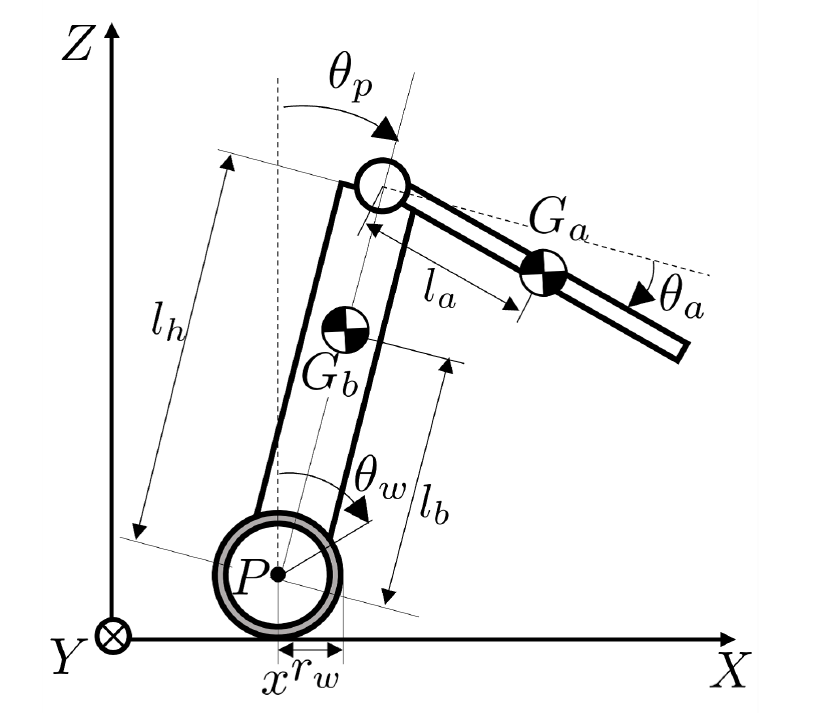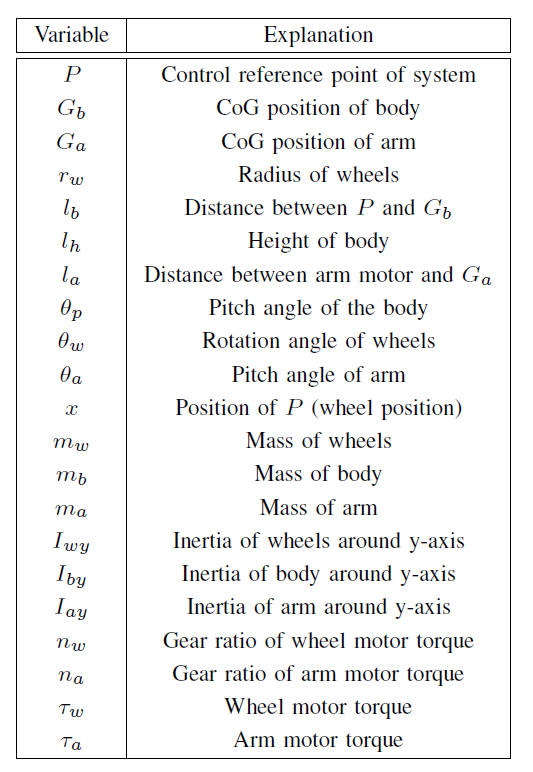

syms t g rw lb lh la th_p(t) dth_p ddth_p th_a(t) dth_a ddth_a th_w(t) dth_w ddth_w mw mb ma Iw Ib Ia nw na tau_w tau_a
Rp = simplify([cos(pi/2-th_p(t)) -sin(pi/2-th_p(t));
      sin(pi/2-th_p(t)) cos(pi/2-th_p(t))]);

% To compare with Makoto change -th_a -> th_a
Ra = [cos(th_a(t)) -sin(th_a(t));
      sin(th_a(t)) cos(th_a(t))];


% Linear velocity robot
v = [diff(th_w(t)*rw); 0];

% --Wheels--

% Linear velocity
vw = v;

% Angular velocity
ww = v(1)/rw;

% Generalized velocity vector
vtw = [vw; ww];

% Unified inertia
Itw = 2*[mw 0 0;
         0 mw 0;
         0 0 Iw];

% Kinetic energy
Kw = 1/2*vtw.'*Itw*vtw;

% --Body--

% CoG coordinates w.r.t. R
Gb = Rp*[lb; 0];
% Angular velocity
wb = diff(th_p);

% Linear velocity
vb = vw+diff(Gb);


% Generalized velocity vector
vtb = [vb; wb];

% Unified inertia
Itb = [mb 0 0;
       0 mb 0;
       0 0 Ib];

% Kinetic energy
Kb = simplify(1/2*vtb.'*Itb*vtb);

% Potential energy
Ub = mb*g*Gb(2);

% --Arm--

% CoG coordinates  w.r.t. P
GaR = simplify(expand(Rp*([lh; 0]+Ra*[0; -la])));

% Angular velocity w.r.t. O
wa = wb + diff(th_a);

% Linear velocity w.r.t. O
va = simplify(v + diff(GaR));

% Generalized velocity vector
vta = [va; wa];

% Unified inertia
Ita = [ma 0 0;
       0 ma 0;
       0 0 Ia];

% Kinetic energy
Ka = simplify(1/2*vta.'*Ita*vta);

% Potential energy
Ua = ma*g*GaR(2);

%--Total Energy--

% Total U
U = Ub+Ua;

%Total K
K = simplify(expand(Kw+Kb+Ka));

% % Potential Energy (U)
% U = mb*g*lb*cos(th_p) + ma*g*(lh*cos(th_p) - la*sin(th_p + th_a));
% 
% % Kinetic Energy (K)
% K = 1/2*(2*mw)*diff(x)^2 + 1/2*(2*Iw)*(diff(x)/rw)^2 + 1/2*Ib*diff(th_p)^2 + 1/2*Ia*(diff(th_p) + diff(th_a))^2 ...
%     + 1/2*mb*((diff(x) + diff(th_p)*lb*cos(th_p))^2 + (diff(th_p)*lb*sin(th_p))^2) ...
%     + 1/2*ma*((diff(x) + diff(th_p)*lh*cos(th_p) - diff(th_a)*la*sin(th_a + th_p))^2 + (diff(th_p)*lh*sin(th_p) + diff(th_a)*la*cos(th_a + th_p))^2);
% K = simplify(expand(K));

% Lagrangian
L = K - U;

% Generalized coordinates
q = [th_w(t), th_p(t), th_a(t)];
dq = [dth_w, dth_p, dth_a];
ddq = [ddth_w, ddth_p, ddth_a];

% Preallocate vectors for dL_dq and dL_dt
dL_dq = sym(zeros(length(q), 1)); % Partial derivatives of L w.r.t. q
dL_dt = sym(zeros(length(q), 1)); % Time derivatives of partial derivatives of L w.r.t. dq

% Compute derivatives
for i = 1:length(q)
    % Partial derivative of L with respect to q(i)
    dL_dq(i) = collect(diff(L, q(i)),[diff(q,2), diff(q), q]);
    
    % Partial derivative of L with respect to dq(i)
    dL_ddq = diff(L, diff(q(i)));
    
    % Time derivative of the above partial derivative
    dL_dt(i) = collect(diff(dL_ddq, t),[diff(q,2), diff(q), q]);
end

% Generalized torques
tau = [nw*tau_w; -nw*tau_w; na*tau_a];

% Euler-Lagrange equation
EL_eq = dL_dt-dL_dq == tau;

% Find inertia matrix
M = subs(EL_eq,[diff(q,2), diff(q), g],[ddq, zeros(1,length(q)), 0]);
M = equationsToMatrix(M,ddq);
M = simplify(expand(M))

$$M = \begin{array}{l} \left(\begin{array}{ccc} 2\,\mathrm{Iw}+\mathrm{ma}\,{\mathrm{rw}}^{2}+\mathrm{mb}\,{\mathrm{rw}}^{2}+2\,\mathrm{mw}\,{\mathrm{rw}}^{2} & \sigma_{2} & \sigma_{3}\\ \sigma_{2} & \mathrm{ma}\,{\mathrm{la}}^{2}+2\,\mathrm{ma}\,\sin\left({\mathrm{th}}_{a}\left(t\right)\right)\,\mathrm{la}\,\mathrm{lh}+\mathrm{mb}\,{\mathrm{lb}}^{2}+\mathrm{ma}\,{\mathrm{lh}}^{2}+\mathrm{Ia}+\mathrm{Ib} & \sigma_{1}\\ \sigma_{3} & \sigma_{1} & \mathrm{ma}\,{\mathrm{la}}^{2}+\mathrm{Ia} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\mathrm{ma}\,{\mathrm{la}}^{2}-\mathrm{lh}\,\mathrm{ma}\,\sin\left({\mathrm{th}}_{a}\left(t\right)\right)\,\mathrm{la}+\mathrm{Ia}\\ \sigma_{2}=-\sigma_{3}+\mathrm{lb}\,\mathrm{mb}\,\mathrm{rw}\,\cos\left({\mathrm{th}}_{p}\left(t\right)\right)+\mathrm{lh}\,\mathrm{ma}\,\mathrm{rw}\,\cos\left({\mathrm{th}}_{p}\left(t\right)\right)\\ \sigma_{3}=-\mathrm{la}\,\mathrm{ma}\,\mathrm{rw}\,\sin\left({\mathrm{th}}_{a}\left(t\right)-{\mathrm{th}}_{p}\left(t\right)\right) \end{array}$$


% Find coriolis and centripetal matrix
H = lhs(subs(EL_eq,[diff(q,2), diff(q), g],[zeros(1,length(q)), diff(q), 0]));
H = simplify(expand(H))

$$H = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{la}\,\mathrm{ma}\,\mathrm{rw}\,\sigma_{1}\,\frac{\partial }{\partial t}{\mathrm{th}}_{p}\left(t\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{a}\left(t\right)-\mathrm{lh}\,\mathrm{ma}\,\mathrm{rw}\,\sin\left({\mathrm{th}}_{p}\left(t\right)\right)\,\sigma_{2}-\mathrm{la}\,\mathrm{ma}\,\mathrm{rw}\,\sigma_{1}\,{\left(\frac{\partial }{\partial t}{\mathrm{th}}_{a}\left(t\right)\right)}^{2}-\mathrm{la}\,\mathrm{ma}\,\mathrm{rw}\,\sigma_{1}\,\sigma_{2}-\mathrm{lb}\,\mathrm{mb}\,\mathrm{rw}\,\sin\left({\mathrm{th}}_{p}\left(t\right)\right)\,\sigma_{2}\\ -\mathrm{la}\,\mathrm{lh}\,\mathrm{ma}\,\cos\left({\mathrm{th}}_{a}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}{\mathrm{th}}_{a}\left(t\right)-2\,\frac{\partial }{\partial t}{\mathrm{th}}_{p}\left(t\right)\right)\,\frac{\partial }{\partial t}{\mathrm{th}}_{a}\left(t\right)\\ -\mathrm{la}\,\mathrm{lh}\,\mathrm{ma}\,\cos\left({\mathrm{th}}_{a}\left(t\right)\right)\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left({\mathrm{th}}_{a}\left(t\right)-{\mathrm{th}}_{p}\left(t\right)\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}{\mathrm{th}}_{p}\left(t\right)\right)}^{2} \end{array}$$


% Find gravitational matrix
G = lhs(subs(EL_eq,[diff(q,2), diff(q), g],[zeros(1,length(q)), zeros(1,length(q)), g]));
G = simplify(G)

$$G = \left(\begin{array}{c} 0\\ -g\,\mathrm{ma}\,\left(\mathrm{lh}\,\sin\left({\mathrm{th}}_{p}\left(t\right)\right)+\mathrm{la}\,\cos\left({\mathrm{th}}_{a}\left(t\right)-{\mathrm{th}}_{p}\left(t\right)\right)\right)-g\,\mathrm{lb}\,\mathrm{mb}\,\sin\left({\mathrm{th}}_{p}\left(t\right)\right)\\ g\,\mathrm{la}\,\mathrm{ma}\,\cos\left({\mathrm{th}}_{a}\left(t\right)-{\mathrm{th}}_{p}\left(t\right)\right) \end{array}\right)$$